#### Microsoft Call Option Outcomes with Expected Rise

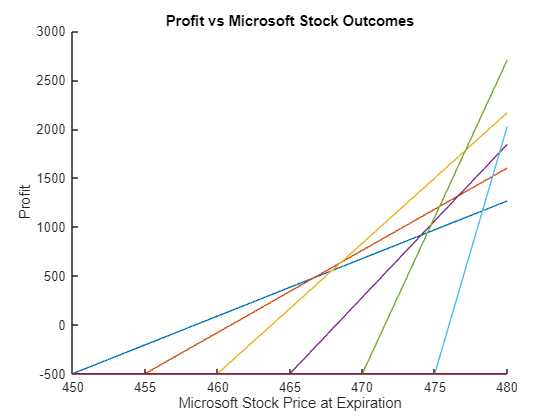

Microsoft_Outcomes = 450:.01:480;

Option_Strikes = [450 455 460 465 470 475 480];
Option_Prices = [8.5 5.95 3.75 3.2 1.56 .99 .6];

Option_Outcomes = nan(length(Option_Prices),length(Microsoft_Outcomes));

figure
hold on
for row_index = 1:length(Option_Prices)
    num_options = 500/Option_Prices(row_index); % Assume that we only spend $500 on Options
    Option_Outcomes(row_index,:) = max(Microsoft_Outcomes-Option_Strikes(row_index),0) - Option_Prices(row_index);
    plot(Microsoft_Outcomes,num_options*Option_Outcomes(row_index,:))
end
xlabel('Microsoft Stock Price at Expiration')
ylabel('Profit')
title('Profit vs Microsoft Stock Outcomes')

#### Expected Value Based Analysis

% Checks:

% Does Black Scholes Params for generated Geometric Brownian Motion match
% expected?

test_mu = .05;
test_sigma = .31;
[~,open_prices] = geometric_brownian_motion(100,1,1e4,test_mu,test_sigma);
clear("stock_data")
stock_data(length(open_prices)) = struct();
for index = 1:length(open_prices)
    stock_data(index).Open = open_prices(index);
end
test_black_scholes_params = estimate_black_scholes_parameters(stock_data,1e-4,'Open')

test_black_scholes_params = struct with fields:
           best_mu: 0
        best_sigma: 0.3100
       mu_interval: [0 1]
    sigma_interval: [0.3000 0.3100]






filename = "C:\Users\wynga\OneDrive\Desktop\PhD_Research\Options Trading\MSFT.csv";
stock_data = read_yahoo_finance_csv(filename);


black_scholes_params = estimate_black_scholes_parameters(stock_data,1e-4,'Open')

black_scholes_params = struct with fields:
           best_mu: 0.3250
        best_sigma: 0.2040
       mu_interval: [-0.1000 0.7250]
    sigma_interval: [0.1945 0.2324]


% Historic Volatility for the year is approximately 21.3
% https://marketchameleon.com/Overview/MSFT/IV/

% Checks:

% Does Black Scholes Params for generated Geometric Brownian Motion match
% expected?




spot_price = 449.15;
mu = black_scholes_params.best_mu;
sigma = black_scholes_params.best_sigma;
time_to_expiration = 19/365;
option_type = 'Call';
option_price = 5.95;
strike_price = 455;
max_price = 600;

[expected_value,variance] = black_scholes_expected_value(spot_price,mu,sigma,time_to_expiration,...
                            option_type,option_price,strike_price,'max_price',max_price)

expected_value = 3.9979

variance = 188.3041

standard_deviation = sqrt(variance)

standard_deviation = 13.7224


% Check:
% Does Numerical runs of Expected Value with generated
% Geometric_Brownian_Motion match expected?





% Checks:

% Does Black Scholes Params for generated Geometric Brownian Motion match
% expected?

% Does Numerical runs of Expected Value with generated
% Geometric_Brownian_Motion match expected?
